Fs = 1e4;%サンプル周波数
t = 0:1/Fs:1;
%加速度センサの感度
Vg_Chest = 0.66;
Vg_NeckSkin = 0.2;
Vg_NeckStrap = 0.2;
Vg_Tention = 0.12427;

FolderNum = 10;
AllData = cell(FolderNum,1);
nharm = 6;%thdの高調波数

%10列2行のセルを作成。1列目にy軸加速度の行列、2列目に力センサ
%（できれば1-の連番にして一々ファイル名を変更しないでも良いようにしたい


for k =1 : FolderNum
    switch k
        case 1
            cd 10\
            DataName = '10Hz';
        case 2
            cd 15\
            DataName = '15Hz';            
        case 3
            cd 22\
            DataName = '20Hz';
        case 4
            cd 33\
            DataName = '33Hz';
        case 5
            cd 47\
            DataName = '47Hz';
        case 6
            cd 68\
            DataName = '68Hz';
        case 7
            cd 100\
            DataName = '100Hz';
        case 8
            cd 150\
            DataName = '150Hz';
        case 9
            cd 220\
            DataName = '220Hz';
        case 10
            cd 330\
            DataName = '330Hz';
    end
list = dir('*.csv');
numFiles = length(list);
Mx = cell(numFiles,2);    
G = cell(numFiles,2);


    for i = 1:numFiles
    %   importFile = sprintf('tek00%d.csv', i); %i.csvの名前のファイルをインポート
    %     Mx{i,1} = csvread(importFile,21,1,[21,1,10020,3]); %ファイル名をi.csvでインポート。21～10020列まで、2～4行目まで
        Mx{i,1}= csvread(list(i).name,21,1,[21,1,10020,2]);
        
        [Chest_thd_db,Chest_harmpow,Chest_harmfreq] = thd(Mx{i,1}(:,1),Fs,nharm); 
        [NeckSkin_thd_db,NeckSkin_harmpow,NeckSkin_harmfreq] = thd(Mx{i,1}(:,2),Fs,nharm);
%         [NeckStrap_thd_db,NeckStrap_harmpow,NeckStrap_harmfreq] = thd(Mx{i,1}(:,3),Fs,nharm);
%         [Input_thd_db,Input_harmpow,Input_harmfreq] = thd(Mx{i,1}(:,4),Fs,nharm);
            Mx{i,2}(:,1) = Chest_thd_db;
            Mx{i,2}(:,2) = NeckSkin_thd_db;
%             Mx{i,2}(:,3) = NeckStrap_thd_db;
%             Mx{i,2}(:,4) = Input_thd_db;
            Mx{i,3}(:,1) = Chest_harmpow;
            Mx{i,3}(:,2) = NeckSkin_harmpow;
%             Mx{i,3}(:,3) = NeckStrap_harmpow;
%             Mx{i,3}(:,4) = Input_harmpow;
            Mx{i,4}(:,1) = Chest_harmfreq;
            Mx{i,4}(:,2) = NeckSkin_harmfreq;
%             Mx{i,4}(:,3) = NeckStrap_harmfreq;
%             Mx{i,4}(:,4) = Input_harmfreq;
            Mx{i,5}(:,1) = 100*(10^(Chest_thd_db/20));
            Mx{i,5}(:,2) = 100*(10^(NeckSkin_thd_db/20));
%             Mx{i,5}(:,3) = 100*(10^(NeckStrap_thd_db/20));        
%             Mx{i,5}(:,4) = 100*(10^(Input_thd_db/20));
            
        %各RMS値計算
        Mx{i,6}(:,1) = rms(Mx{i,1}(:,1)) / Vg_Tention;
%         Mx{i,6}(:,2) = rms(Mx{i,1}(:,2)) / Vg_NeckSkin;        
%         Mx{i,6}(:,3) = rms(Mx{i,1}(:,3)) / Vg_NeckStrap;
        Mx{i,6}(:,2) = 2*sqrt(2)*rms(Mx{i,1}(:,2));
        
        %グラフ用のセルに整頓
        G{i,1} = Mx{i,6}(:,2);%入力信号のRMS
        %THD
        G{i,2}(:,1) = Mx{i,5}(:,1);
        G{i,2}(:,2) = Mx{i,5}(:,2);
%         G{i,2}(:,3) = Mx{i,5}(:,3);
%         G{i,2}(:,4) = Mx{i,5}(:,4);
        %RMS
        G{i,3}(:,1) = Mx{i,6}(:,1);
%         G{i,3}(:,2) = Mx{i,6}(:,2);
%         G{i,3}(:,3) = Mx{i,6}(:,3);
      
        AllData{k,1} = DataName;
        AllData{k,2} = Mx;
    end

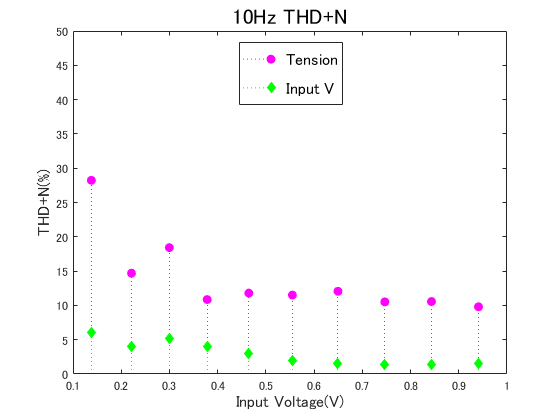

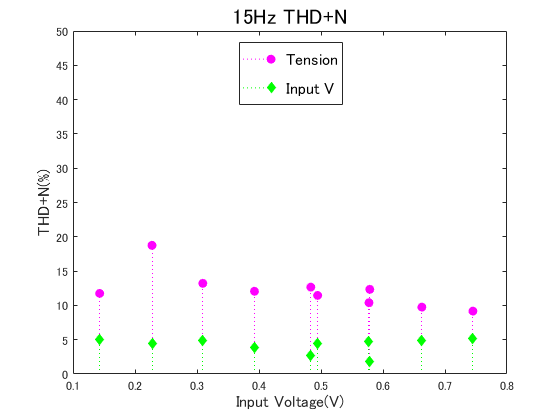

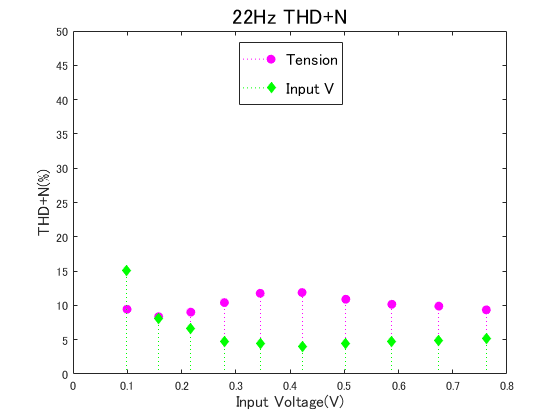

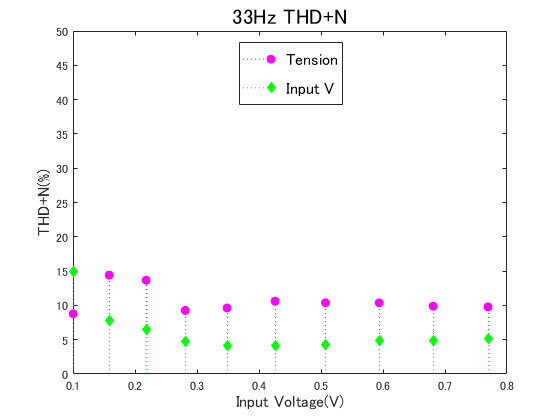

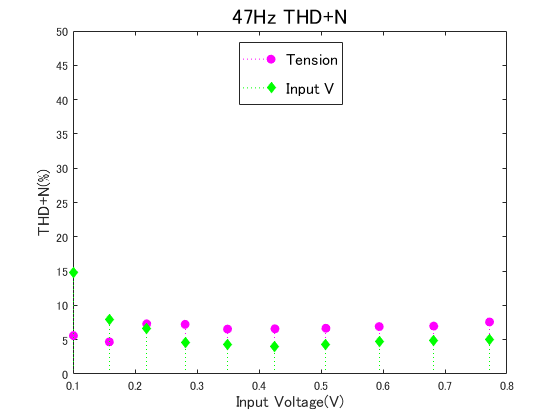

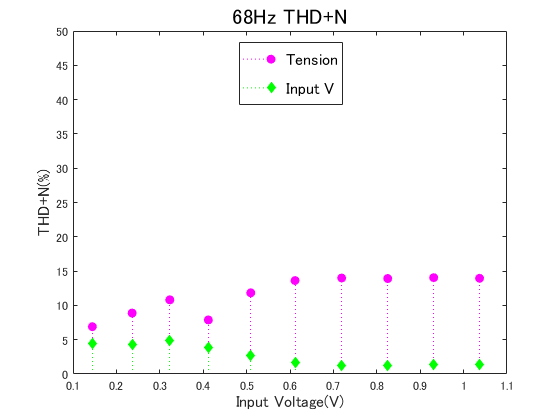

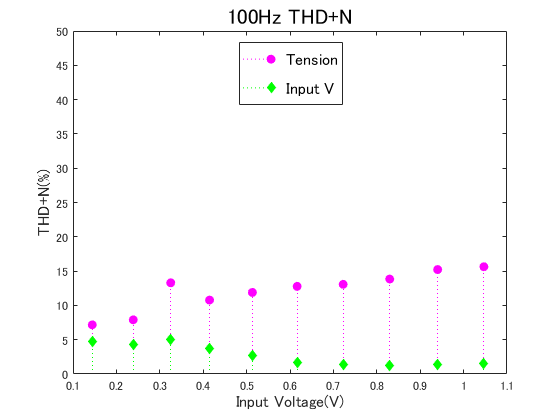

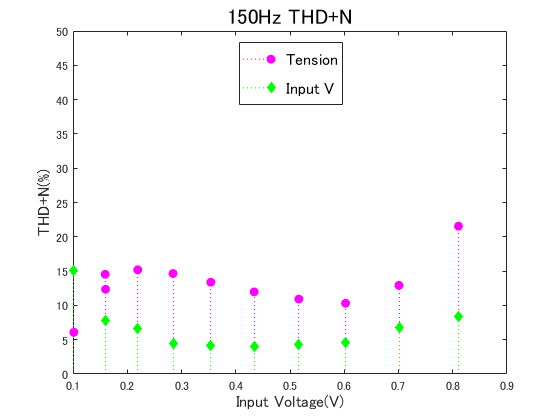

Frequency = num2str(round(Mx{1,4}(1,2))); %周波数を文字列表示
GraphTitleTHD = strcat(Frequency,'Hz THD+N');
GraphTitleRMS = strcat(Frequency,'Hz Tention');

graphdata = cell2mat(G);

stem(graphdata(:,1),graphdata(:,2),'filled','LineStyle',':','Color','m','Marker','o'); %加速度グラフ
hold on
stem(graphdata(:,1),graphdata(:,3),'filled','LineStyle',':','Color','g','Marker','diamond'); %張力のグラフ 
% stem(graphdata(:,1),graphdata(:,4),'filled','LineStyle',':','Color','m','Marker','square');  %入力電圧
% stem(graphdata(:,1),graphdata(:,5),'filled','LineStyle',':','Color','g','Marker','square');  %入力電圧
legend('Tension','Input V','Position',[0.47 0.75 0.1 0.15],'fontsize',12);
% set(gca,'xscale','log');    %x軸をlogscaleに
xlabel('Input Voltage(V)','fontsize',12);
ylabel('THD+N(%)','fontsize',12);
ylim([0 50]);
title(GraphTitleTHD, 'fontsize',16)
hold off


% stem(graphdata(:,1),graphdata(:,4),'filled','LineStyle',':','Color','y','Marker','o'); %加速度グラフ
% hold on
% % stem(graphdata(:,1),graphdata(:,7),'filled','LineStyle',':','Color','b','Marker','diamond'); %張力のグラフ 
% % stem(graphdata(:,1),graphdata(:,8),'filled','LineStyle',':','Color','m','Marker','square');  %入力電圧
% legend('Tention',[0.47 0.75 0.1 0.15],'fontsize',12);
% % set(gca,'xscale','log');    %x軸をlogscaleに
% xlabel('Input Voltage(V)','fontsize',12);
% ylabel('Tention(N)','fontsize',12);
% ylim([0 2]);
% title(GraphTitleRMS, 'fontsize',16)
% hold off


cd ..
end
   
% C = vertcat(AllData{i,2}{10,1})
for i = 1:10
C{i,1} = AllData{i,2}{10,1};
end

Cx = vertcat(C{1,1},C{2,1},C{3,1},C{4,1},C{5,1},C{6,1},C{7,1},C{8,1},C{9,1},C{10,1});